clc
%clear all
close all

a = 0;
b = 50;
N = 1000;
h = (b-a)/N;
fprintf("步长为:%f",h)

步长为:0.050000

t0 = a:h:b;

% 解析解作图
syms t
X = dsolve('D2x=-5*x-0.2*Dx','x(0)=0','Dx(0)=1','t')

$$X = \frac{10\,\sqrt{499}\,{\mathrm{e}}^{-\frac{t}{10}}\,\sin\left(\frac{\sqrt{499}\,t}{10}\right)}{499}$$

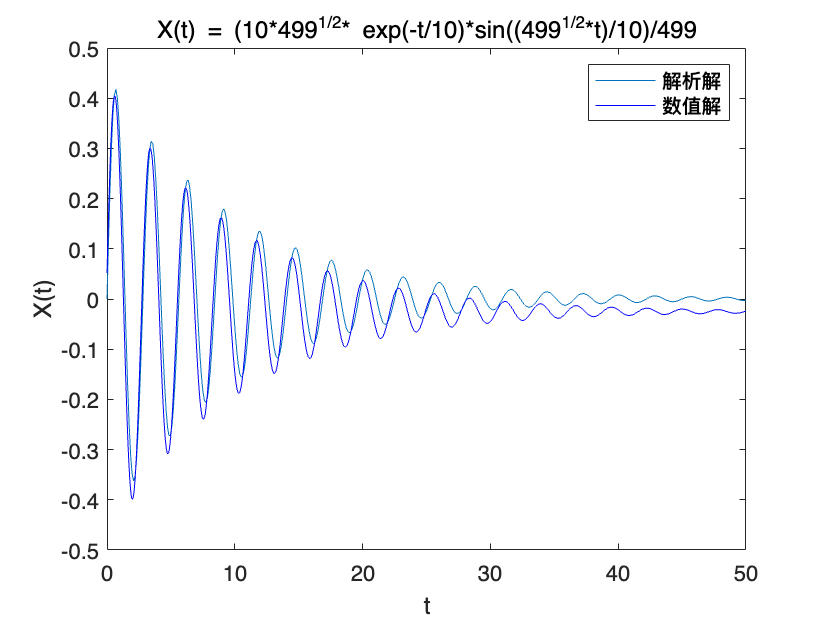

ezplot(X,[a,b]);
ylim([-0.5,0.5]);
hold on

%%先将二阶转换成一阶,令y = x'(t), y' = x''(t),则y'=-5x-0.2y

u(1) = 0;
u(2) = 1;

for i = 1:length(t0)
    u = RK(u,h);
    Result(i,:) = u;
end

% 绘制位移图
plot(t0,Result(:,1),'b')      
xlabel('t')
ylabel('X(t)')

legend('解析解','数值解');
title('X(t) = ({10}*{499}^{{1}/{2}}* {exp}(-{t}/{10})*{sin}(({499}^{{1}/{2}}*{t})/{10})/{499}')


hold off

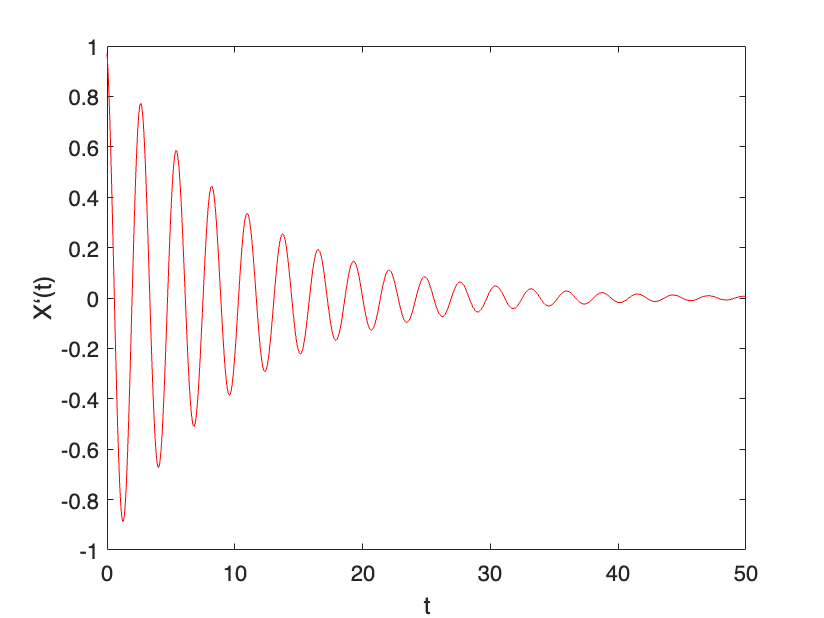


% 绘制速度图
plot(t0,Result(:,2),'r')      
xlabel('t')
ylabel('X‘(t)')


%-动图---------------------------------
for i=1:1000
plot(t0(i),Result(i,1),'.m','MarkerSize',20);
axis([0 50 -0.5 0.5]);
pause(0.01)
end
%-------------------------------------


function u = RK(u,h)
%设位移x(t)为u(1), 速度x'(t)为u(2),
%此处的  dx/dt = f(t,x)= x' 故只需代入u(2)...t为自变量..
KK1=u(2);
KK2=u(2)+h/2*KK1;
KK3=u(2)+h/2*KK2;
KK4=u(2)+h*KK3;
u(1)=u(1)+h/6*(KK1+2*KK2+2*KK3+KK4);

K1=odefun(u(1),u(2));
K2=odefun(u(1)+h/2,u(2)+h/2*K1);
K3=odefun(u(1)+h/2,u(2)+h/2*K2);
K4=odefun(u(1)+h,u(2)+h*K3);
u(2)=u(2)+h/6*(K1+2*K2+2*K3+K4);
end

function dy = odefun(x,y)
dy = -5*x-0.2*y;
end